clear
clc
digits(6)

I = 5; % [A]
sigma = 1; % [A/V]

R = 2;

angle_source = 0;
angle_sink = 180;
% angle_source = [0 180];
% angle_sink = 90 + [0 180];
% angle_source = 0;
% angle_sink = [120 240];

angle_v = 60;

source = [R*cosd(angle_source); R*sind(angle_source)]';
sink = [R*cosd(angle_sink); R*sind(angle_sink)]';
% v1 = [R*cosd(angle_v),R*sind(angle_v)];
% v2 = [R*cosd(angle_v+120),R*sind(angle_v+120)];
v1 = [-1,2];
v2 = [1,2];
v3 = [R*cosd(angle_v+240),R*sind(angle_v+240)];

points_v = [v1; v2; v3];

syms r a b c d x y theta
syms phi(x,y) psi(x,y) Phi(x,y) Psi(x,y)
F(r) = a + b * log(r) + c * r^2 + d * r^2 * log(r);

phi(r,theta) = simplify(1/r * diff(r * diff(F(r),r),r));
phi(x,y) = subs(phi(r,theta),r,sqrt(x^2+y^2));
phi(x,y) = subs(phi(x,y),c,-d);
phi(x,y) = vpa(subs(phi(x,y),d,I/(2*pi)/sigma/4))

$$phi(x, y) = 0.795775\,\log\left(\sqrt{x^{2}+y^{2}}\right)$$


psi(x,y) = vpa(simplify(int(diff(phi(x,y),x),y)));
psi(x,y) = str2sym(replace(replace(string(psi),"atan","atan2"),'/',','))

$$psi(x, y) = 0.795775\,\text{atan2}\left(y,x\right)$$


Phi(x,y) = 0;
Psi(x,y) = 0;
for i = 1:size(source,1)
   Phi(x,y) = Phi(x,y) + (phi(x-source(i,1),y-source(i,2)));
   Psi(x,y) = Psi(x,y) + (psi(x-source(i,1),y-source(i,2)));
end
for i = 1:size(sink,1)
   Phi(x,y) = Phi(x,y) - (phi(x-sink(i,1),y-sink(i,2)));
   Psi(x,y) = Psi(x,y) - (psi(x-sink(i,1),y-sink(i,2)));
end

dV12 = double(Phi(v1(1),v1(2)) - Phi(v2(1),v2(2)))

dV12 = 0.7604

dV23 = double(Phi(v2(1),v2(2)) - Phi(v3(1),v3(2)))

dV23 = 0.0569

dV31 = double(Phi(v3(1),v3(2)) - Phi(v1(1),v1(2)))

dV31 = -0.8173

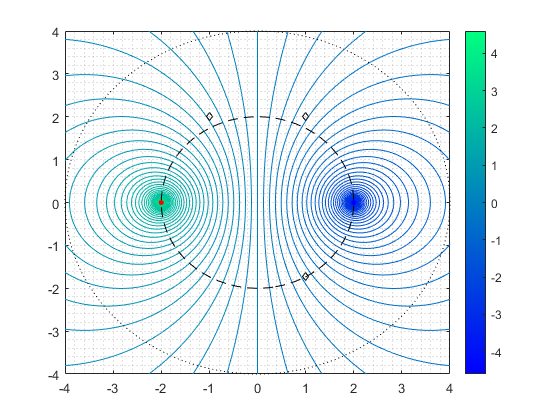


figure(1)
fc_phi = fcontour(Phi, ...
    'MeshDensity',400, ...
    'Fill',"off");
fc_phi.LevelList = -5:0.1:5;
hold on

% fc_psi = fcontour(Psi,'--', ...
%     'MeshDensity',400, ...
%     'LineWidth',1);
% fc_psi.LevelList = -0.5:0.05:0.5;

circle_base(x,y) = (x.^2 + y.^2) - R^2;
circle_range(x,y) = (x.^2 + y.^2) - (2*R)^2;
fimplicit(circle_base(x,y),'k--');
fimplicit(circle_range(x,y),'k:');

scatter(source(:,1),source(:,2),16,'bo','filled');
scatter(sink(:,1),sink(:,2),16,'ro','filled');
scatter(points_v(:,1),points_v(:,2),24,'kd');

hold off
grid minor
xlim([-2*R,2*R]);
ylim([-2*R,2*R]);

colormap("winter");
colorbar;

% th = linspace(0,2*pi,100);
% x_ = 2*R*cos(th);
% y_ = 2*R*sin(th);
% for i = 1:length(th)
%     phi_(i) = double(Phi(x_(i),y_(i))); %#ok
% end